# Electromagnetic Analysis of Intelligent Reflecting Surface

This example shows how to model the response of an intelligent reflecting surface (IRS) using full-wave electromagnetic simulation. The IRS, also known as the reconfigurable intelligent surface (RIS), large intelligent surface (LIS), or metasurface, has garnered significant interest in the wireless communication community. The IRS consists of a large array of subwavelength unit cell elements which can manipulate the phase, amplitude, polarization, or frequency of the incident signal. If an obstacle blocks the direct path between the base station (BS) and the user equipment (UE), the parasitic reflection of the IRS can provide an alternative path for signal transmission, as this figure shows. An external phase control mechanism can be integrated to control the reflection characteristics of the IRS.

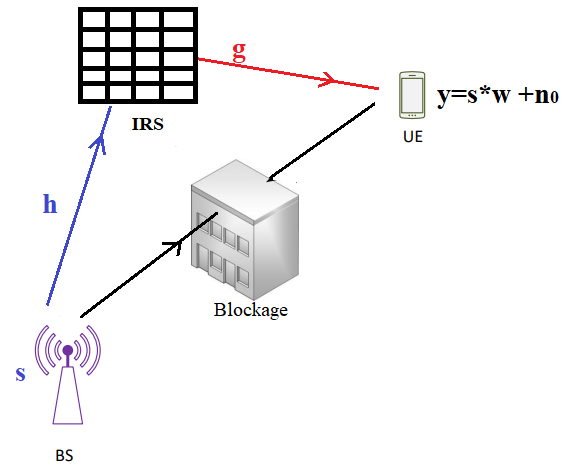

The inclusion of the RIS provides a two-segment indirect path to the signal traveling between the BS and the UE. The first segment covers the path between the BS and the IRS. The second segment covers the path between the IRS and the UE. The channel matrix of these two signal paths depends on the geometry and the electromagnetic reflection properties of the IRS.

The signal received at the UE is represented mathematically in [1] using this equation.

$r=sw+n_0=s\frac{\sqrt{G_rG_uG_tA_rA_u}}{4\pi}\sum_{n=1}^N \frac{\sqrt{\tilde{F}_n}R_n}{d_{tn}d_{rn}}e^\frac{-j2\pi(d_{tn}+d_{rn})}{\lambda}+n_0$,

where

- 
$$R=[R_1~R_2~......R_n]^T.$$


- $G_u$ is the embedded gain of the $n^{th}$ IRS element.

- $G_t$ is the embedded gain of the BS transmitter.

- $G_r$ is the embedded gain of the UE receiver.

- $F_n=F_n^tF_n^rF_{n}^{tx}F^{rx}_n$ is the product of the normalized power patterns of the BS, UE, and IRS.

- $d_t$ is the distance between the BS and the $n^{th}$ IRS element.

- $d_r$ is the distance between the UE and the $n^{th}$ IRS element.

- $A_r$ is the  effective aperture area of the UE.

- $A_u$ is the effective aperture area of the $n^{th}$ IRS element.

- $\lambda$ is the free-space wavelength.

For this example, assume that the IRS has $$N$$ unit cell elements. The complex reflection coefficient of the $n^{th}$ IRS element is denoted by $R_n=R^{mag}_n e^{j\tau_n}$.

The reflection coefficients of the IRS depend on these factors:

- Direction and polarization of the incoming signal towards the IRS.

- Direction and polarization of the outgoing signal from the IRS.

- Material properties and geometry of the IRS.

This example focuses on varying the incident signal configurations and determining the corresponding reflection characteristics.

Assume that $d_{tn}$ and $d_{rn}$ are in the far-field range. You can abstract the IRS as [infiniteArray](docid:antenna_ref#bvfg_q0-1) catalog element with a [planeWaveExcitation](docid:antenna_ref#bvj2_xq-1) model.

## Configuring the IRS

We assume the IRS is oriented to the yz plane

Calculating the distances between the elements in the scenario: BS, IRS, MU, and observation points in the XY plane.

%calculating the spatial location of the IRS elements
pos_IRS_n=cell(N_v,N_h);%stores the position of the IRS elements
%distance from the transmitter to the IRS elements
d_t_n=zeros(N_v,N_h);
%distance from the receiver to the IRS
d_r_n_1=zeros(N_v,N_h);
d_r_n_2=zeros(N_v,N_h);
%distance from the observation points to the IRS elements
d_obs_n=zeros(N_v,N_h,ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));

x=1;
y=1;
for i=1:N_v
    for j=1:N_h
        %nth-IRS element positions
        pos_IRS_n{i,j}=pos_IRS+(N_v/2-0.5-(i-1))*[0 0 1]*D_h+...
                               ((j-1)-N_h/2+0.5)*[0 1 0]*D_h;
        %nth-IRS element distance to the transmitter
        d_t_n(i,j)=norm(pos_IRS_n{i,j}-pos_tx);
        %nth-IRS element distance to the receiver
        d_r_n_1(i,j)=norm(pos_IRS_n{i,j}-pos_rx_1);
        %nth-Obs element distance to the observation point
        for x=1:ceil((x_max-x_min)/grid_size)
            for y=1:ceil((y_max-y_min)/grid_size)
                d_obs_n(i,j,x,y)=norm(pos_IRS_n{i,j}-pos_obs{x,y});
            end
        end
        %
        
    end
end


Calculating the CIR between the BS and the nth-elementIRS

%see [1, Eq. (2)]
h_t_n=sqrt(A_u*F_tx_n*F_t_n./(4*pi*d_t_n.^2)).*exp(-1i*2*pi*d_t_n/lambda);


Calculating the received signal by the MU at the BS with the observation point. In the following loop three steps are implemented per observation point:

- The CIR between the nth-element IRS and the observation point is calculated

- The IRS is optimally configured with [1, Eq. (9)]

- The coefficient w is calculated with [1, Eq. (6)]

- The received signal is calculated with [1, Eq. (7)]

g_obs_n=zeros(N_v,N_h,ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
w_xy=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
R_temp=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
w_xy_temp=zeros(ceil((x_max-x_min)/grid_size),ceil((y_max-y_min)/grid_size));
for x=1:ceil((x_max-x_min)/grid_size)
    for y=1:ceil((y_max-y_min)/grid_size)
        %CIR between the nth-element IRS and the
        % observation point; see [1, Eq. (4)]
        g_obs_n(:,:,x,y)=sqrt(A_u*F_rx_n*F_r_n./(4*pi*d_obs_n(:,:,x,y).^2)).*exp(-1i*2*pi*d_obs_n(:,:,x,y)/lambda);
        %optimally configuring the IRS; see  [1, Eq. (9)]
        R=conj(g_obs_n(:,:,x,y)).*conj(h_t_n)./abs(conj(g_obs_n(:,:,x,y)).*conj(h_t_n));
        %Calculating the w coeff
        F=F_tx_n.*F_t_n.*F_rx_n.*F_r_n;
        w_xy(x,y)=sqrt(Gr*Gu*Gt*A_r*A_u)/(4*pi)*sum(sum(sqrt(F).*R./(d_t_n.*d_r_n_1).*exp((-1i*2*pi*(d_t_n+d_r_n_1))/lambda)));

    end
end

#### Measuring the localization errors

ans = 0.1023

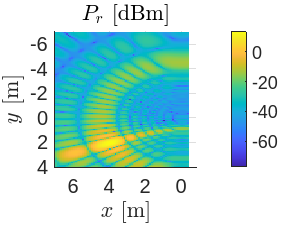

%localizing the maximum
[MU_loc,I]=max(abs(w_xy),[],'all','linear');
[rows,cols]=size(w_xy);
col_max=floor(I/rows);
row_max=I-col_max*rows;
abs(w_xy(row_max,col_max+1));
%measuring the error
x=linspace(x_min,x_max,ceil((x_max-x_min)/grid_size));
y=linspace(y_min,y_max,ceil((y_max-y_min)/grid_size));
norm(pos_rx_1-[x(row_max) y(col_max+1) 0])

## Reference

[1] Cui, Yaoshen, Haifan Yin, Li Tan, and Marco Di Renzo., " A 3D Positioning-based Channel Estimation Method for RIS-aided mmWave Communications." arXiv:2203.14636 (April 21, 2022). [https://doi.org/10.48550/arXiv.2203.14636](https://doi.org/10.48550/arXiv.2203.14636).

*Copyright 2022 The MathWorks, Inc.*